clear all, close all;
addpath('..\');
addpath('..\float_model\')
addpath('..\hardware_handling\')

setenv('PATH', [getenv('PATH') ';C:\tools\Xilinx\Vivado\2024.1\bin']);


%SAMPLING_FREQ = (50*16*16);
SAMPLING_FREQ = 10^8;
BUFFER_LEN = 2048;
SIM_TIME = 12*BUFFER_LEN/SAMPLING_FREQ

SIM_TIME = 2.4576e-04

FREQ = SAMPLING_FREQ*(0 : BUFFER_LEN-1)/BUFFER_LEN;
MAIN_FREQ_INDEX = 9;
AMPLITUDE_NORMAL = 2.001;
csv_read;

out = sim("hdl_model_fixed.slx")

out =   Simulink.SimulationOutput:

                logsout: [1x1 Simulink.SimulationData.Dataset] 
                   tout: [614401x1 double] 
                   yout: [1x1 Simulink.SimulationData.Dataset] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


out2 = sim("hdl_model.slx")

out2 =   Simulink.SimulationOutput:

                   tout: [43009x1 double] 
                   yout: [1x1 Simulink.SimulationData.Dataset] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


sim_FFT= out.yout{1}.Values;
sim_MAX = out.yout{3}.Values;
sim_MIN = out.yout{4}.Values;
sim_THD = out.yout{5}.Values;
sim_RMS = out.yout{6}.Values;
sim_VAL = out.yout{7}.Values;

sim_FFT_fl= out2.yout{1}.Values;
sim_RMS_fl = out2.yout{2}.Values;
sim_MIN_fl = out2.yout{3}.Values;
sim_MAX_fl = out2.yout{4}.Values;
sim_THD_fl = out2.yout{5}.Values;
sim_BUF_fl = out2.yout{6}.Values;
sim_VAL_fl = out2.yout{7}.Values;

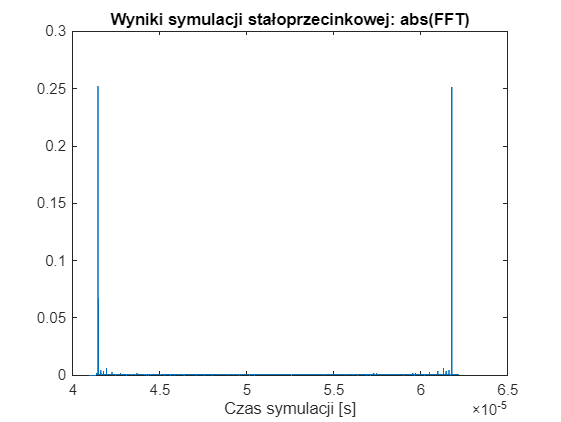

figure;
plot(sim_FFT.Time(2*BUFFER_LEN:3*BUFFER_LEN+80, :), abs(sim_FFT.Data(2*BUFFER_LEN:3*BUFFER_LEN+80, :)));
title("Wyniki symulacji stałoprzecinkowej: abs(FFT)")
xlabel("Czas symulacji [s]")

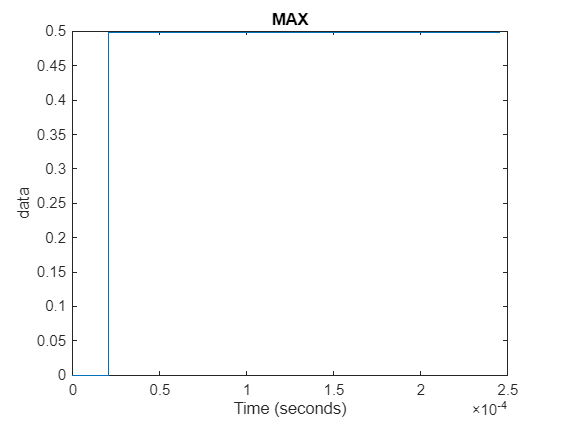


figure;
plot(sim_MAX);
title("MAX")

disp(sim_MAX.Data(end, :))

    0.4990



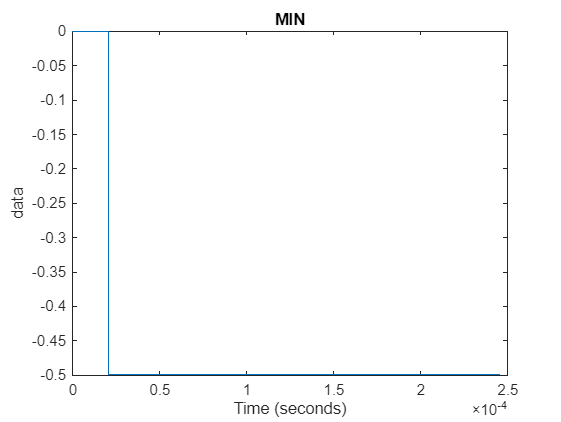


figure;
plot(sim_MIN);
title("MIN")

disp(sim_MIN.Data(end, :))

   -0.4995



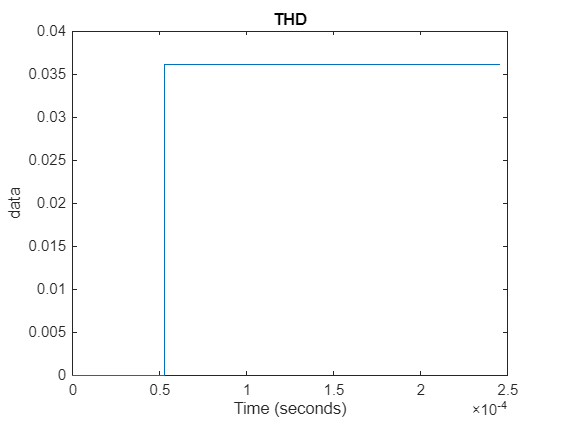


figure;
plot(sim_THD);
title("THD")

disp(sim_THD.Data(end, :))

    0.0361



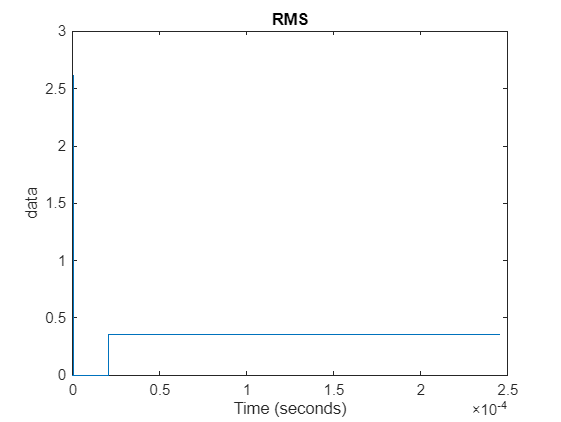


figure;
plot(sim_RMS);
title("RMS")

disp(sim_RMS.Data(end, :))

    0.3555



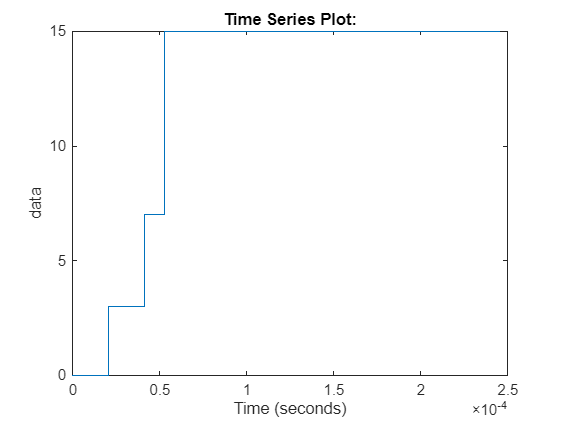


figure;
plot(sim_VAL);

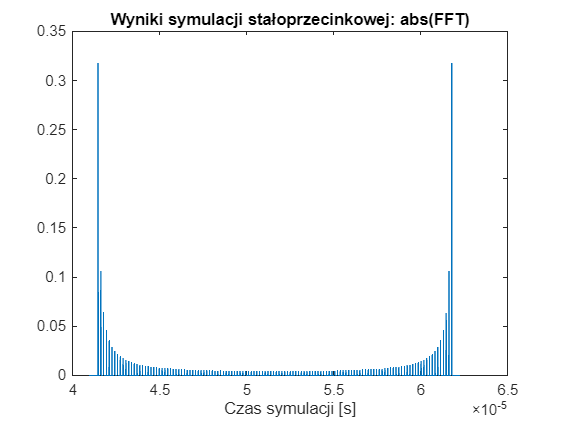

figure;
plot(sim_FFT_fl.Time(2*BUFFER_LEN:3*BUFFER_LEN+80, :), abs(sim_FFT_fl.Data(2*BUFFER_LEN:3*BUFFER_LEN+80, :)));
title("Wyniki symulacji stałoprzecinkowej: abs(FFT)")
xlabel("Czas symulacji [s]")

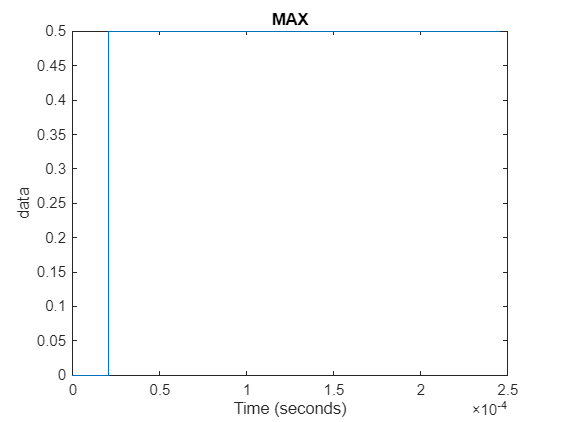


figure;
plot(sim_MAX_fl);
title("MAX")

disp(sim_MAX_fl.Data(end, :))

    0.4998



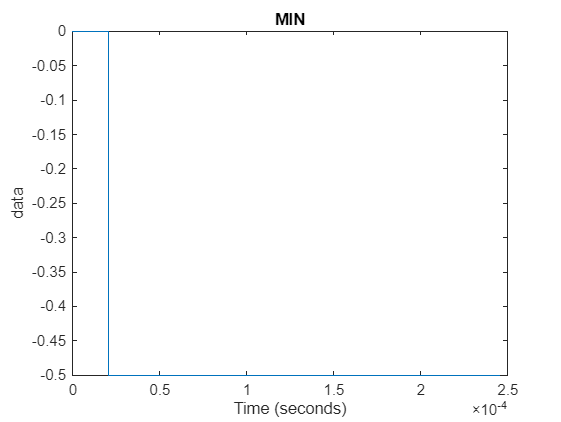


figure;
plot(sim_MIN_fl);
title("MIN")

disp(sim_MIN_fl.Data(end, :))

   -0.4998



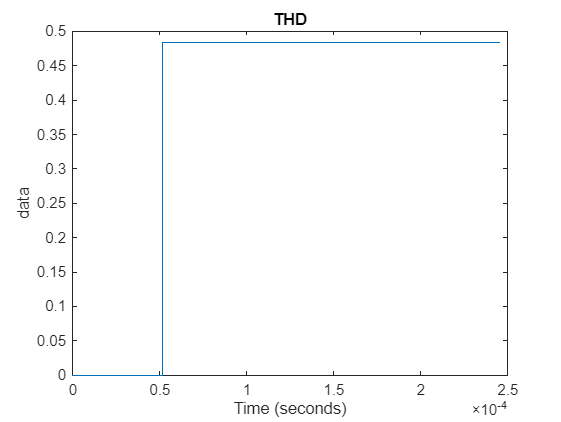


figure;
plot(sim_THD_fl);
title("THD")

disp(sim_THD_fl.Data(end, :))

    0.4834



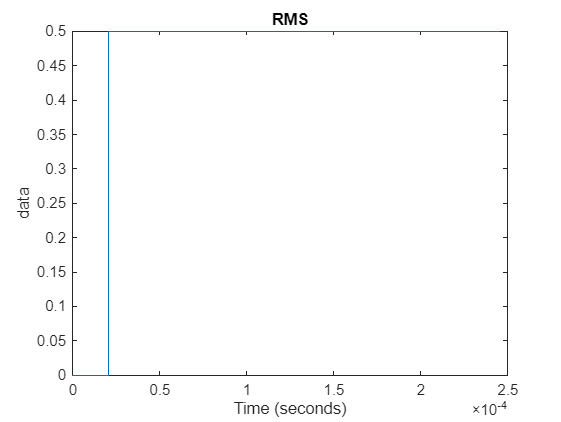


figure;
plot(sim_RMS_fl);
title("RMS")

disp(sim_RMS_fl.Data(end, :))

    0.4998



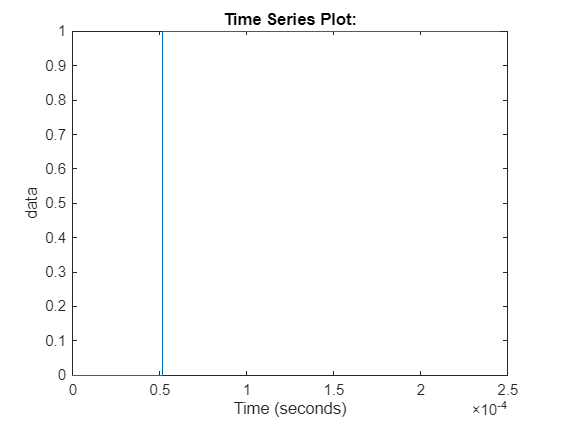


figure;
plot(sim_VAL_fl);

diff_caption = "Różnica symulacji stałoprzecinkowej i zmiennoprzecinkowej: "

diff_caption = "Różnica symulacji stałoprzecinkowej i zmiennoprzecinkowej: "

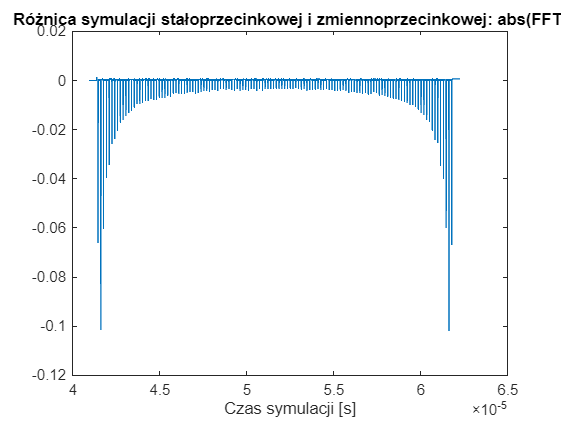


figure;
plot(sim_FFT.time(2*BUFFER_LEN:3*BUFFER_LEN+80, :), abs(sim_FFT.Data(2*BUFFER_LEN:3*BUFFER_LEN+80, :))-abs(sim_FFT_fl.Data(2*BUFFER_LEN:3*BUFFER_LEN+80, :)));
title(diff_caption + "abs(FFT)")
xlabel("Czas symulacji [s]")

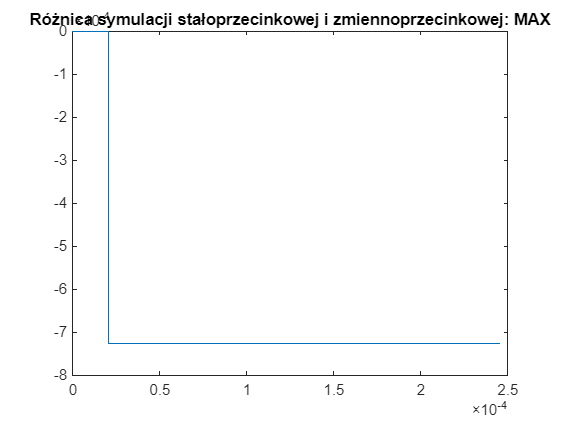


figure;
plot(sim_MAX.time, sim_MAX.Data-sim_MAX_fl.Data);
title(diff_caption + "MAX")

disp(sim_MAX.Data(end, :)-sim_MAX_fl.Data(end, :))

  -7.2669e-04



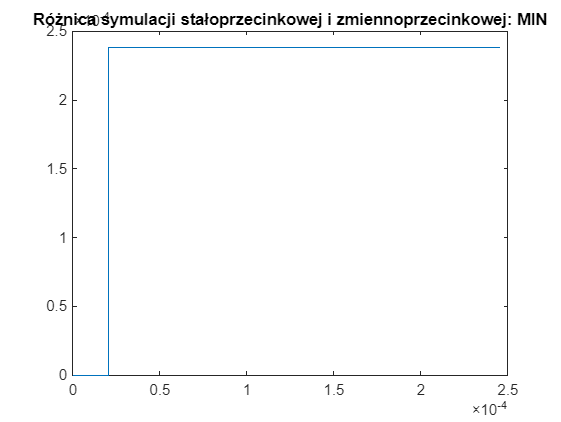


figure;
plot(sim_MIN.time, sim_MIN.Data-sim_MIN_fl.Data);
title(diff_caption + "MIN")

disp(sim_MIN.Data(end, :)-sim_MIN_fl.Data(end, :))

   2.3841e-04



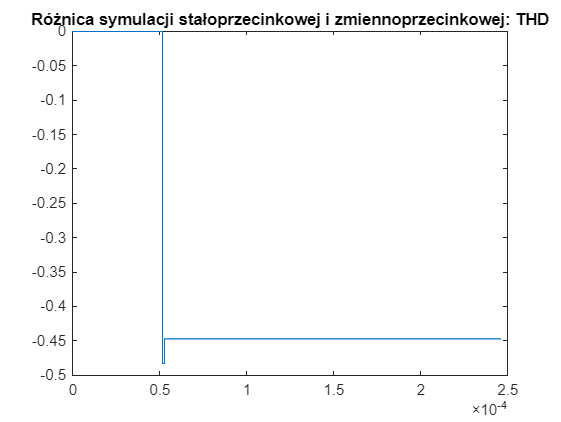


figure;
plot(sim_THD.time, sim_THD.Data-sim_THD_fl.Data);
title(diff_caption + "THD")

disp(sim_THD.Data(end, :)-sim_THD_fl.Data(end, :))

   -0.4472



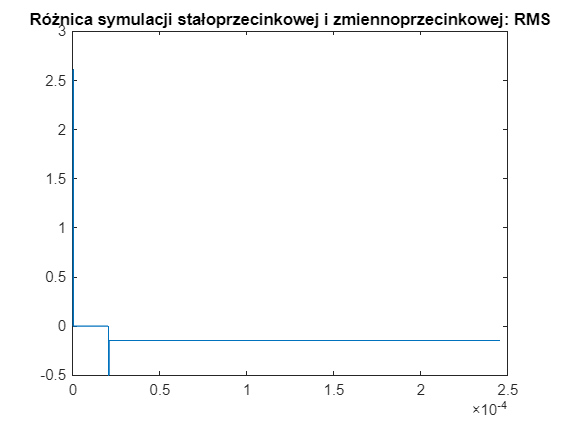


figure;
plot(sim_RMS.time, sim_RMS.Data-sim_RMS_fl.Data);
title(diff_caption + "RMS")

disp(sim_RMS.Data(end, :)-sim_RMS_fl.Data(end, :))

   -0.1443



### Zynq eval

get_zynq_fft;

zynq_caption = "Różnica symulacji stałoprzecinkowej i wyniku z modelu fizycznego "

zynq_caption = "Różnica symulacji stałoprzecinkowej i wyniku z modelu fizycznego "

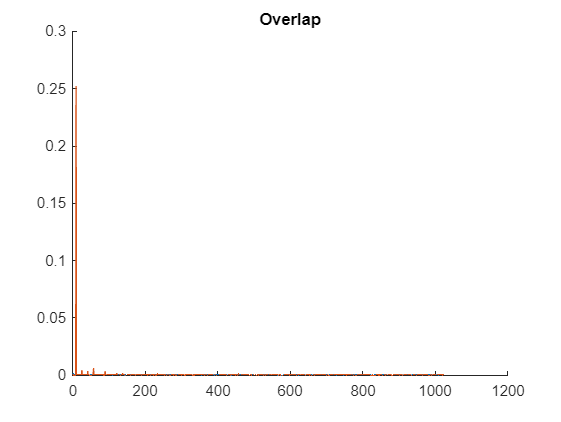


start_time = 2*BUFFER_LEN+42;
end_time = start_time + BUFFER_LEN/2;

sim_FFT_tozynq = abs(sim_FFT.Data(start_time:end_time-1, :))';

difference = sim_FFT_tozynq - zynq_signal_absolut;

figure;
hold on;
plot(sim_FFT_tozynq)
plot(zynq_signal_absolut)
title("Overlap");
hold off

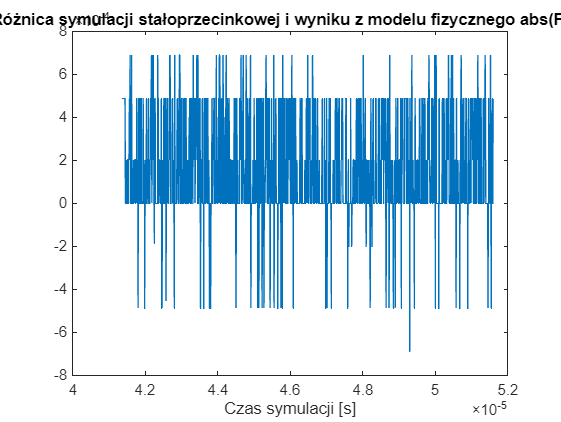


figure;
plot(sim_FFT.time(start_time:end_time-1, :), difference);
title(zynq_caption + "abs(FFT)")
xlabel("Czas symulacji [s]")